% % 定义三角形三个顶点的坐标
% A = [1, 0, 0];
% B = [0, 1, 0];
% C = [0, 0, 0];
% 
% % 定义直线的方向角 theta 和仰角 beta（假设三条直线相同）
% theta = 0; % 假设 theta1, theta2, theta3 相同
% beta = 90; % 假设 beta1, beta2, beta3 相同
% 
% % 计算直线的方向向量
% dir = [cosd(beta)*cosd(theta), cosd(beta)*sind(theta), sind(beta)];
% 
% % 计算三角形平面的法向量
% normal = cross(B-A, C-A);
% normal = normal / norm(normal);
% 
% % 计算反射方向向量
% reflect_dir1 = dir - 2*dot(dir, normal)*normal;
% reflect_dir2 = dir - 2*dot(dir, normal)*normal;
% reflect_dir3 = dir - 2*dot(dir, normal)*normal;
% 
% % 定义反射直线的参数方程 r = P + t*reflect_dir
% syms t;
% r1 = A + t*reflect_dir1;
% r2 = B + t*reflect_dir2;
% r3 = C + t*reflect_dir3;
% 
% % 计算反射直线与平面 z = 1 的交点
% z = 1;
% t1 = solve(r1(3) == z, t);
% t2 = solve(r2(3) == z, t);
% t3 = solve(r3(3) == z, t);
% 
% point1 = double(subs(r1, t, t1));
% point2 = double(subs(r2, t, t2));
% point3 = double(subs(r3, t, t3));
% 
% % 输出交点
% fprintf('反射直线1与平面z=1的交点为: (%.2f, %.2f, %.2f)\n', point1);
% fprintf('反射直线2与平面z=1的交点为: (%.2f, %.2f, %.2f)\n', point2);
% fprintf('反射直线3与平面z=1的交点为: (%.2f, %.2f, %.2f)\n', point3);
% 
% % 定义圆盘的圆心和半径
% circle_center = [0, 0, z];
% radius = 0.5; % 假设圆盘的半径为0.5
% 
% % 计算反射交点形成的三角形面积
% triangle_area = 0.5 * norm(cross(point2 - point1, point3 - point1));
% 
% % 计算圆盘与三角形的重合面积
% % 使用蒙特卡罗方法进行近似计算
% N = 100000; % 随机点的数量
% inside_circle = 0;
% inside_triangle = 0;
% 
% for i = 1:N
%     % 生成随机点
%     rand_x = (2 * radius) * (rand - 0.5);
%     rand_y = (2 * radius) * (rand - 0.5);
%     point = [rand_x, rand_y];
% 
%     % 判断点是否在圆盘内
%     if norm(point) <= radius
%         inside_circle = inside_circle + 1;
% 
%         % 判断点是否在三角形内
%         if inpolygon(rand_x, rand_y, [point1(1), point2(1), point3(1)], [point1(2), point2(2), point3(2)])
%             inside_triangle = inside_triangle + 1;
%         end
%     end
% end
% 
% % 计算重合面积
% circle_area = pi * radius^2;
% overlap_area = circle_area * (inside_triangle / inside_circle);
% 
% % 计算重合面积与反射交点形成的三角形面积之比
% ratio = overlap_area / triangle_area;
% 
% % 输出结果
% fprintf('重合面积与反射交点形成的三角形面积之比为: %.4f\n', ratio);
% 

% 定义三角形三个顶点的坐标
A = [0, 0, -300.4];
B = [6.1078,8.407,-300.2202];
C = [9.8827,-3.211,-300.2202];

% 定义直线的方向角 theta 和仰角 beta（假设三条直线相同）
theta = 0; % 假设 theta1, theta2, theta3 相同
beta = 90; % 假设 beta1, beta2, beta3 相同

% 计算直线的方向向量
dir = [cosd(beta)*cosd(theta), cosd(beta)*sind(theta), sind(beta)];

% 计算三角形平面的法向量
normal = cross(B-A, C-A);
normal = normal / norm(normal);

% 计算反射方向向量
reflect_dir1 = dir - 2*dot(dir, normal)*normal;
reflect_dir2 = dir - 2*dot(dir, normal)*normal;
reflect_dir3 = dir - 2*dot(dir, normal)*normal;

% 定义反射直线的参数方程 r = P + t*reflect_dir
syms t;
r1 = A + t*reflect_dir1;
r2 = B + t*reflect_dir2;
r3 = C + t*reflect_dir3;

% 计算反射直线与馈源舱平面 z = -160.4136 的交点
z = -160.4136;
t1 = solve(r1(3) == z, t);
t2 = solve(r2(3) == z, t);
t3 = solve(r3(3) == z, t);

point1 = double(subs(r1, t, t1));
point2 = double(subs(r2, t, t2));
point3 = double(subs(r3, t, t3));

% 输出交点
fprintf('反射直线1与平面z的交点为: (%.2f, %.2f, %.2f)\n', point1);

反射直线1与平面z的交点为: (-5.70, -1.85, -160.41)


fprintf('反射直线2与平面z的交点为: (%.2f, %.2f, %.2f)\n', point2);

反射直线2与平面z的交点为: (0.42, 6.56, -160.41)


fprintf('反射直线3与平面z的交点为: (%.2f, %.2f, %.2f)\n', point3);

反射直线3与平面z的交点为: (4.19, -5.06, -160.41)



% 定义圆盘的圆心和半径
circle_center = [0, 0, z];
radius = 0.5; % 假设圆盘的半径为0.5

% 计算反射交点形成的三角形面积
triangle_area = 0.5 * norm(cross(point2 - point1, point3 - point1));

% 计算圆盘与三角形的重合面积
% 使用蒙特卡罗方法进行近似计算
N = 100000; % 随机点的数量
inside_circle = 0;
inside_triangle = 0;

for i = 1:N
    % 生成随机点
    rand_x = (2 * radius) * (rand - 0.5);
    rand_y = (2 * radius) * (rand - 0.5);
    point = [rand_x, rand_y];
    
    % 判断点是否在圆盘内
    if norm(point) <= radius
        inside_circle = inside_circle + 1;
        
        % 判断点是否在三角形内
        if inpolygon(rand_x, rand_y, [point1(1), point2(1), point3(1)], [point1(2), point2(2), point3(2)])
            inside_triangle = inside_triangle + 1;
        end
    end
end

% 计算重合面积
circle_area = pi * radius^2;
overlap_area = circle_area * (inside_triangle / inside_circle);

% 计算重合面积与反射交点形成的三角形面积之比
ratio = overlap_area / triangle_area;

% 输出结果
fprintf('重合面积与反射交点形成的三角形面积之比为: %.4f\n', ratio);

重合面积与反射交点形成的三角形面积之比为: 0.0153


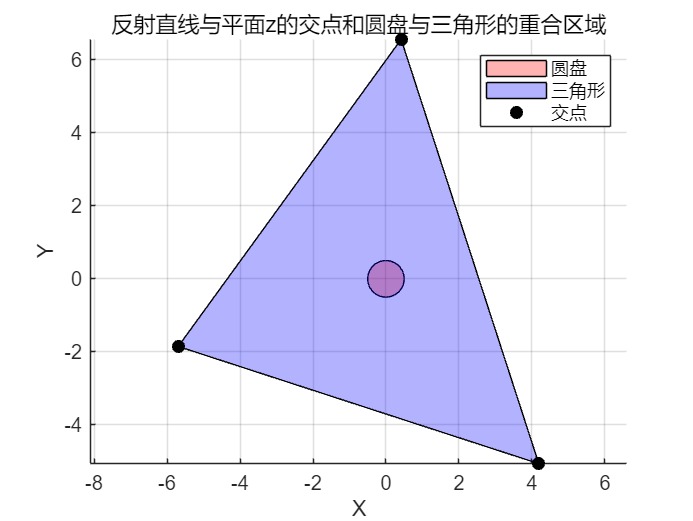


% 画出二维图像
figure;
hold on;

% 画出圆盘
theta_circle = linspace(0, 2*pi, 100);
x_circle = radius * cos(theta_circle);
y_circle = radius * sin(theta_circle);
fill(x_circle, y_circle, 'r', 'FaceAlpha', 0.3);

% 画出三角形
fill([point1(1), point2(1), point3(1)], [point1(2), point2(2), point3(2)], 'b', 'FaceAlpha', 0.3);

% 标记交点
plot(point1(1), point1(2), 'ko', 'MarkerFaceColor', 'k');
plot(point2(1), point2(2), 'ko', 'MarkerFaceColor', 'k');
plot(point3(1), point3(2), 'ko', 'MarkerFaceColor', 'k');

% 设置图形属性
axis equal;
xlabel('X');
ylabel('Y');
title('反射直线与平面z的交点和圆盘与三角形的重合区域');
legend('圆盘', '三角形', '交点');
grid on;
hold off;